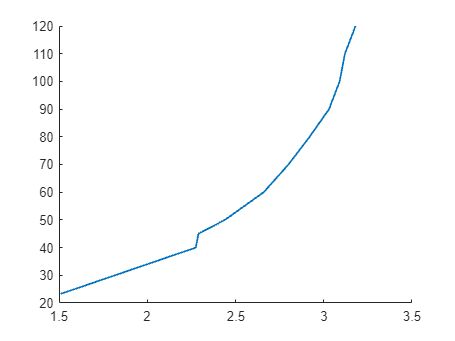

syms R T
V1 = 3.3-2.44;
V2 = 3.3-2.66;
V3 = 3.3-2.80;

I1 = 2.44/10e3;
I2 = 2.66/10e3;
I3 = 2.80/10e3;

R1 = V1/I1;
R2 = V2/I2;
R3 = V3/I3;

L1 = log(R1);
L2 = log(R2);
L3 = log(R3);

Y1 = 1/(50+273.15);
Y2 = 1/(60+273.15);
Y3 = 1/(70+273.15);

gamma2 = (Y2-Y1)/(L2-L1);
gamma3 = (Y3-Y1)/(L3-L1);

C = ((gamma3-gamma2)/(L3-L2))/(L1+L2+L3);
B = gamma2-C*(L1^2+L1*L2+L2^2);
A = Y1-(B+L1^2*C)*L1;

v = [1.51  2.29 2.44 2.66 2.80 2.92 3.03 3.09 3.12 3.18];
T = [23.3 40 45 50 60 70 80 90 100 110 120];
p4 = polyfit(v, T, 4);
x = 1.51:0.01:3.3;
y4 = polyval(p4, x);
% plot(x,y4)

hold on
p3 = polyfit(v, T, 3);
y3 = polyval(p3, x);
% plot(x,y3)
% interp1(x,y3,23.3)
plot(v, T, "LineWidth", 1.25)
% xlim([23 120])
hold off